# Fundamental statistical principles

#### Vectors and matrices

**Vectors** describe locations in multidimensional space. Each element of a vector describes a dimension in space. If a vector can take on any set of values in *n*-dimensional space, we say that is lies in $\mathbb{R}^n$. By convention, we'll use column vectors in our notation, and row vectors will be indicated by their transpose, a'.  


$$\mathbf{a} = {\brack{\matrix{a_1 \cr a_2 \cr a_3}}}  \\$$
   
$$\mathbf{a^T} = {\brack{\matrix{a_1 a_2 a_3}}}  $$


**Matrices**, in the way we use them here in statistical models, generally describe a set of *m* observations in *n*-dimensional space. Rows usually represent observations, and columns dimensions. So an [*m* x *n*] matrix may describe a dataset of *m* subjects measured on *n* independent variables. If these measures are predictors in a linear model, these constitute a **design matrix**, *X* (or sometimes *Z*).    

A vector transposed times itself is the sum of the element-wise products of the elements. This is the [**dot product**](https://en.wikipedia.org/wiki/Dot_product) or the **scalar product** in linear algebra. It is fundamental to measures of similarity, variance, and other aspects of the linear model equations.


$$\mathbf{a} \cdot \mathbf{b} = a^Tb = b^Ta = \sum_{i=1}^{n} a_i b_i$$


With a vector with three elements, which represents a point in three-dimensional space, this is:


$$\mathbf{a} \cdot \mathbf{b} = a_x b_x + a_y b_y + a_z b_z
$$


In matrix notation, this works out to:


$$\mathbf{a} \cdot \mathbf{b} = a^Tb=a'b={\brack{\matrix{a_1 & a_2 & a_3}}} \cdot {\brack{\matrix{b_1 \cr b_2 \cr b_3}}}  $$


#### **Vector similarity and distance**

The dot product of two vectors x and y is related to both their magnitudes and the similarity of the angle between them. We can think of it as a scale-dependent measure of similarity.


$$x{\cdot}y=||x|| \cdot ||y|| \spacecos(\theta_{xy})$$


The cosine of the angle between the vectors is called the **cosine similarity, **and it provides a "scale-free" measure of similarity**:**


$$cos(\theta_{xy}) =\frac{\mathbf{x} \cdot \mathbf{y}}{\| \mathbf{x} \| \cdot \| \mathbf{y} \|}
$$


This is a commonly used distance metric, where the distance is related to the similarity of the two vectors in multidimensional space.  

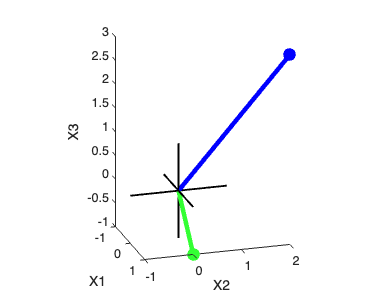

x = [1 2 3]';
y = [1 0 -1]';

% Plot two vectors in 3-D space: a in blue, b in green.
draw_3d_axes(1);
draw_vector(x, 'b');
draw_vector(y, [.2 1 .2]);


% define an anonymous function that calculates cosine sim 
cos_sim = @(x, y) x'*y ./ (norm(x) * norm(y));

% calculate the cosine sim
cossim_xy = cos_sim(x, y)

cossim_xy = -0.3780


% calculate theta, the angle (in radians)
theta_hat = acos(cossim_xy)

theta_hat = 1.9584


% convert radians to degrees. radians = (pi/180) * degrees
theta_hat * 180/pi % in degrees

ans = 112.2077

**Euclidean distances** are calculated as the straight-line distances between points. By the Pythagorean Theorem, c^2 = a^2 + b^2, so c = sqrt(a^2 + b^2). Here, **a** and **b** are dimensions, defined by elements of **x** and **y**. So the dot product $[x-y]^T[x-y]$ is a measure of the squared geometric distance between** x** and **y**. The Euclidean distance is the root mean square. 


eucliddist = @(x, y) ((x - y)' * (x - y)) .^ 0.5

eucliddist = function_handle with value:
    @(x,y)((x-y)'*(x-y)).^0.5



% is the same as 

eucliddist2 = @(x, y) sqrt(sum((x - y).^2))

eucliddist2 = function_handle with value:
    @(x,y)sqrt(sum((x-y).^2))



eucliddist(x, y)

ans = 4.4721

eucliddist2(x, y)

ans = 4.4721


% The stats toolbox function pdist calculates distances between any set of
% points (vectors), where rows define the points and columns the dimensions
% of the space.
d = pdist([x'; y'], 'Euclidean')

d = 4.4721

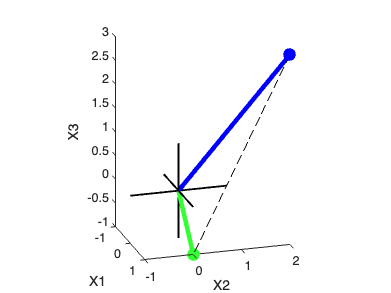


% Plot two vectors in 3-D space: a in blue, b in green.
% Show the distance as a dashed black line.
draw_3d_axes(1);
draw_vector(x, 'b');
draw_vector(y, [.2 1 .2]);
han = plot3([x(1) y(1)]', [x(2) y(2)]', [x(3) y(3)]', '--','Color', 'k', 'LineWidth', 1);

#### **Vector magnitude, norm, and sums of squares **

$x'x$ is the sum of squared values.  

x = [1 2 3]'

x =      1
     2
     3


x' * x

ans = 14

disp('1^2 + 2^2 + 3^2')

1^2 + 2^2 + 3^2


In geometric terms, the square root of $x'x$, or $\sqrt{||x||$, is the distance from zero. This is the vector's **magnitude**, also known as it's **2-norm** or **L2-norm, **or** Euclidean norm.  **A **unit vector** is a vector with a magnitude of 1, often used to represent a direction without regard to magnitude.

The dot product $x'x$ is a measure of the squared geometric distance from 0. The Euclidean distance from zero is its square root. 

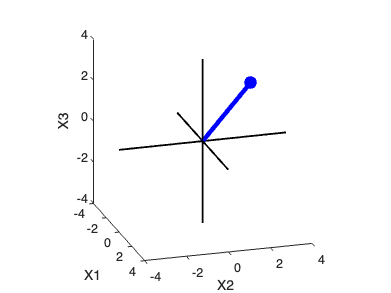

draw_3d_axes(4);

draw_vector(x, 'b');

In a linear model, the 3 dimensions here can represent observations or model predictors, depending on the equation in question. 

If zero is a meaningful value, then $x'x$ takes on particular meaning. For example, if *x* is an [*m *x 1] vector of residuals from *m* observations, *e*, from a linear model, then $e'e$ is the **sums of squared errors (SSE).  **So the SSE is (1) the norm of the error vector and (2) the distance of the error vector from 0 in a space defined my *m* independent observations. 

The **mean squared error** (MSE) is the average squared error per observation (element of *e*), or $\frac{x'x}{m}$

#### **Covariance and correlation**

Often, the mean of a vector is uninteresting, and we want to understand how observations vary around the mean.  This is generally true in statistics, where we are usually interested in analyzing variation among observations. 

**Variance** is a measure of deviations around a sample mean. It is defined as the mean squared deviation from the sample mean, divided by the** degrees of freedom** (df). The **df** is the number of independent dimensions along which scores can vary.  Here this is the number of independent observations - 1 (as we have estimated the mean).  Here we use *m* - 1 instead of *m* to account for the loss of a degree of freedom when estimating the sample mean:


$$var(x) =\frac{(x-\bar{x})^T(x-\bar{x})}{m-1}=\frac{{||x||^2}}{m-1}
$$
 

The standard deviation is the square root of variance. If e is a vector of errors from a model:


$$var(e)=\sigma^2, std(e)=\sigma$$


Covariance is a measure of similarity of shared deviations from a mean. The covariance of two m-length vectors *x* and *y* is:


$$cov(x,y) =\frac{(x-\bar{x})^T(y-\bar{y})}{m-1}
$$


Covariance is often defined in terms of the expected values of **random variables,** which do not have discrete values but instead are **:**


$$\text{Cov}(X, Y) = E\left[(X - E[X])(Y - E[Y])\right]
$$



$$\text{Cov}(X, Y) = E[XY]-E[X]E[Y]
$$


% Generate instances of two normally distributed random variables a and b,
% with m = 10 observations each
a = randn(10, 1);
b = randn(10, 1);

cv = cov(a, b)                     % covariance

cv =     0.7390    0.4001
    0.4001    2.0194


cv2 = (a-mean(a))' * (b-mean(b)) / (length(a) - 1); % covariance

Like the dot product, the units of covariance depend on the **scale** of the variables. For example, we can measure reaction times in seconds or minutes, and changing the units affects the scale of the  response (and thus the mean, variance, and covariance), but not the similarity in reaction times across two tasks. **Correlation** additionally scales each variable by its variance.

For a z-scored variable standardized to mean 0 and standard deviation 1:


$$z_x=(x-\bar{x}) / std(x), z_y=(y-\bar{y}) / std(y)
$$


Pearson's correlation (*r*) is the covariance of the standardized variables:

cov(zscore(a), zscore(b))

ans =     1.0000    0.3275
    0.3275    1.0000


corr(a, b)

ans = 0.3275

r = cv(1, 2) ./ prod(diag(cv) .^ .5)

r = 0.3275

#### **Orthogonality, correlation, and independence**

Orthogonality refers to the concept of two vectors being perpendicular to each other in a given vector space. Mathematically, two vectors ***a*** and ***b*** are orthogonal if and only if their dot product is zero. This means that they are at r*ight angles* to one another. 

Below, we'll plot two vectors in 3-D space: ***a*** in blue, ***b*** in green.

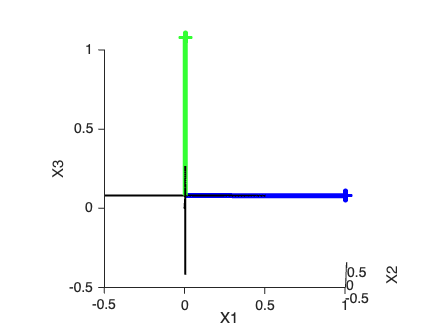

a = [1 0 0]';
b = [0 0 1]';
draw_3d_axes(0.5);
draw_vector(a, 'b');
draw_vector(b, [.2 1 .2]);
view([0.59 9.29])

drawnow, snapnow

Does this mean that they are uncorrelated?

Does it mean that they are linearly independent?						

These are different concepts:

- X and Y are linearly independent iff there is no constant *a *such that **aX** - **Y = 0. **Unless vectors are perfectly aligned so that $|cos(\theta)|=1$, vectors are linearly independent.

- X and Y are orthogonal iff **X'Y = 0**.  All orthogonal vectors are independent, so orthogonality is a special case of independence. 

- X and Y are uncorrelated iff (**X-mean(X))'(Y-mean(Y)) = 0**. Vectors can be orthogonal but not uncorrelated. If both varables are mean-zero and uncorrelated, they must be orthogonal. But if they are not mean-zero, they may be uncorrelated but nonorthogonal.

 Consider the vectors a and b above. 

% Consider orthogonality
dotproduct = a'*b

dotproduct = 0


% Consider the correlation
r = corr(a, b)

r = -0.5000

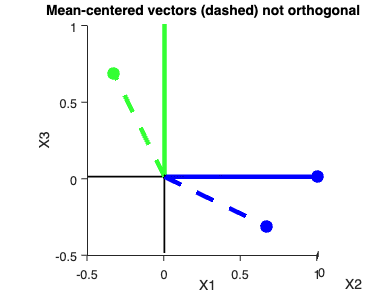


draw_3d_axes(0.5);
draw_vector(a, 'b');
draw_vector(b, [.2 1 .2]);
han = draw_vector(a-mean(a), 'b'); set(han, 'LineStyle','--')
han = draw_vector(b-mean(b), [.2 1 .2]); set(han, 'LineStyle','--')
view([-0.57 -1.51])
title('Mean-centered vectors (dashed) not orthogonal')

Here is a useful Venn diagram of the relationships from this paper:

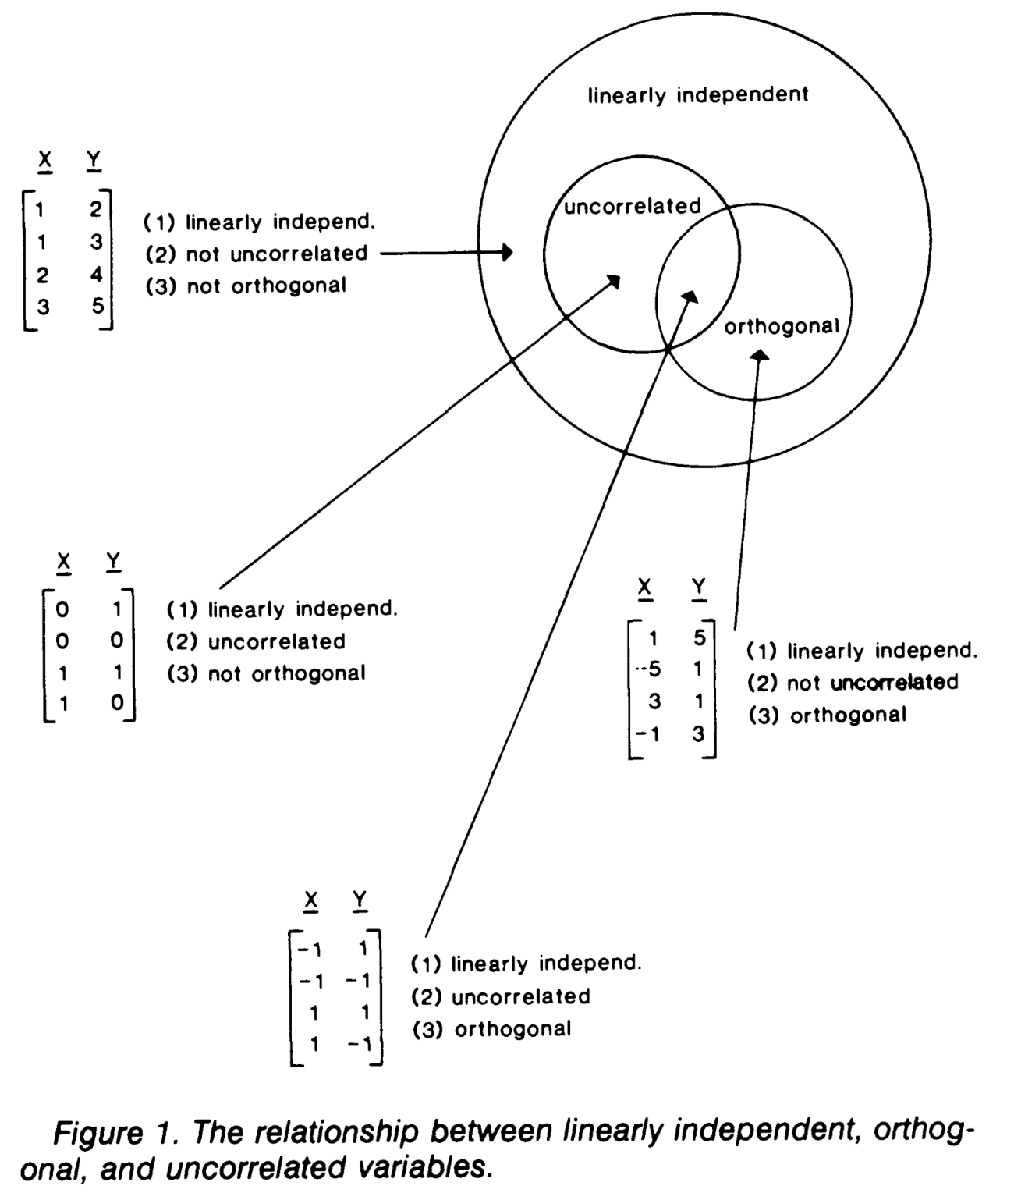

#### Projection

The projection of vector **a** onto vector **b** is the length of vector **a** along the direction defined by vector **b**. We can think of it like the "shadow" of a in the direction defined by b. [This link](https://www.cuemath.com/algebra/dot-product/) or [this one](https://en.wikipedia.org/wiki/Dot_product) has more.


$$proj_b(a)=cos(\theta_{ab})norm(a) =\frac{\mathbf{a} \cdot \mathbf{b}}{\| \mathbf{b} \|}
$$


This gives the scalar projection, a magnitude, to be multiplied by the unit vector in the direction of b, $\frac{\mathbf{b}}{\| \mathbf{b} \|}$

In statistical modeling, **b** will be a predictor (or a set of them defining a model subspace), and **a** will be a data vector that we are projecting onto the model subspace.

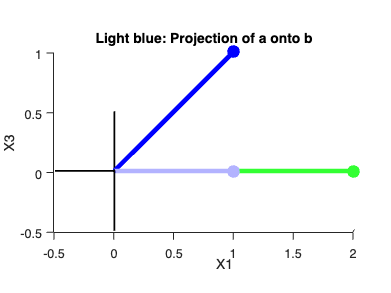

%
a = [1 0 1]';
b = [2 0 0]';

a_onto_b = (a'*b / norm(b)) * (b ./ norm(b));

draw_3d_axes(0.5);
draw_vector(a, 'b');
draw_vector(b, [.2 1 .2]);

han = draw_vector(a, 'b'); set(han, 'LineStyle','--')
han = draw_vector(b, [.2 1 .2]); set(han, 'LineStyle','--')
han = draw_vector(a_onto_b, [.7 .7 1]);

view([-0.57 -1.51])
title('Light blue: Projection of a onto b')

### Extension to matrices

#### Linear combinations

A linear combination is  an expression constructed from a set of terms (variables) by multiplying each term by a scalar (positive or negative) and adding the results. In the context of matrices, it involves multiplying vectors by scalars and adding or subtracting the resulting products.


$$\mathbf{w} = a_1\mathbf{v}_1 + a_2\mathbf{v}_2 + \ldots + a_n\mathbf{v}_n$$


The coefficients $[ a_1\space a_2 \space a_3]$ define the linear combination.

The set of all possible linear combinations of p independent variables includes all points within a p-dimensional **subspace**. In 2-D, this would be a plane, or in 3-D a volume. 


$$\mathbf{v}_1 = \left[ 1, \, 2 \right]^T \\
\mathbf{v}_2 = \left[ 3, \, 4 \right]^T \\
\mathbf{w} = 2\mathbf{v}_1 - 3\mathbf{v}_2 = 2\left[ 1, \, 2 \right]^T - 3\left[ 3, \, 4 \right]^T = \left[ -7, \, -10 \right]^T$$


#### Matrix variance/covariance

If X has multiple columns, X'X is a **square matrix** with the sum of squares on the diagonal, and dot products of its columns on the off-diagonal. This is the *normal matrix* or [Gram matrix](https://en.wikipedia.org/wiki/Gram_matrix). 

X = rand(50, 4);

X =      1     0
     1     0
     1     0
     0     1
     0     1
     0     1


X'*X

It is related to the variance/covariance matrix of the columns of X.  As above, if columns are mean-zero, X'X is the covariance matrix * df.  The df is the number of independent dimensions along which scores can vary, which is the independent observations - 1 (as we have estimated the mean). 

Thus, if X columns are mean-centered, $X'X = cov(X) *(m-1)$

((X-mean(X))' * (X-mean(X))) / (size(X, 1) - 1)

cov(X)  % compare: same

Normal matrix


#### Independence of columns

The number of independent column vectors defines the dimensionality of the space that a matrix spans. This is called the **rank** of the matrix. If X is a design matrix, this is the number of independent predictors (i.e., regressors). 

If the values in the rows fill all the dimensions, the matrix will be **full rank**.  

rank(X)

ans =      3     0
     0     3


Only if a matrix is **full-rank** is its normal matrix invertible. This inversion is critical to solving the normal equation and estimating regression coefficients $\hat\beta$. If the matrix is not full rank, there will be no unique solution for $\hat\beta$, but rather an infinite family of solutions. An intuition for this is that two perfectly redundant predictors should each explain the data (y) equally well, so it's unclear which should be assigned a higher $\hat\beta$.

inv(X'*X)

Inverse normal matrix


Consider Y, which is a copy of X with an additional column. The additional column is a perfect **linear combination** of the other columns, so it "lives within" the existing 4-dimensional space and does not add a new dimension. 

Y = X; Y(:, 5) = X * [.5 .5 -.4 0]'; % The new column of Y is a linear combination of other variables

ans =     0.3333         0
         0    0.3333


rank(Y)


Projection matrix


inv(Y' * Y) % this doesn't work, it's rank deficient

H =     0.3333    0.3333    0.3333         0         0         0
    0.3333    0.3333    0.3333         0         0         0
    0.3333    0.3333    0.3333         0         0         0
         0         0         0    0.3333    0.3333    0.3333
         0         0         0    0.3333    0.3333    0.3333
         0         0         0    0.3333    0.3333    0.3333


#### **Basis sets**

In linear algebra, a basis set is a set of vectors that span a vector space *V*. This defines a coordinate system for vectors in the space. A basis set consists of *p* vectors that satisfies two main properties:

- The vectors are linearly independent, meaning that no vector is a linear combination of the others.

- The vectors span the space V, meaning that there is a linear combination of the basis vectors that can reach any point in the space V. 

For example, 

 
$$\mathbf{e}_1 = {\brack{\matrix{1 \cr 0 \cr 0}}},
\mathbf{e}_2 = {\brack{\matrix{0 \cr 1 \cr 0}}},
\mathbf{e}_3 = {\brack{\matrix{0 \cr 0 \cr 1}}}  \\$$


is the standard basis for $\mathbb{R}^3$, 3-D geometric space. These can be collected into a matrix:


$$E = \left( \begin{array}{ccc}
1 &0 & 0 \\
0 & 1 & 0 \\
0 & 0 & 1
\end{array} \right)$$


If the basis vectors are orthogonal and have a norm = 1, this is an **orthonormal** basis set, and the matrix E is an **orthogonal matrix. **Here, E is the **identity matrix**, the simplest kind of orthogonal matrix.

In the GLM,  columns of the design matrix (*X*) are vectors that provide a basis set. These are usually not orthogonal, though they can be if the design matrix reflects an experimental design with orthogonal factors. The data vector is projected onto the basis set using an optimal linear combination $\hat{\beta}$ to produce fitted values. 

#### **Rotations**

Rotation matrices are [square matrices](https://en.wikipedia.org/wiki/Square_matrix), with [real](https://en.wikipedia.org/wiki/Real_number) entries. More specifically, they can be characterized as [orthogonal matrices](https://en.wikipedia.org/wiki/Orthogonal_matrix) with [determinant](https://en.wikipedia.org/wiki/Determinant) 1. (The determinant can be thought of as related to the volume described by the columns of a matrix. The determinant of the identity matrix is 1). The columns of R form a basis set for the space in which the rotation occurs. 

Orthogonal matrices representing rotations (as opposed to reflections) have a determinant of +1. If the determinant is -1, it represents a reflection. A few properties of rotation matrices include:

- They are square matrices.

- They are orthogonal matrices, meaning their rows and columns are orthonormal unit vectors. Consequently, the inverse of a rotation matrix is simply its transpose ($R^{-1}=R^T$).

- Their determinant is 1 (or -1 if they include reflection).


$$R = \left( \begin{array}{ccc}
\cos(\theta) & -\sin(\theta) & 0 \\
\sin(\theta) & \cos(\theta) & 0 \\
0 & 0 & 1 
\end{array} \right)$$


If the 3 dimensions of *R *are x, y, and z spatial dimensions, respectively, this matrix represents a counterclockwise rotation of $\theta$ radians around the z-axis. The matrix can be extended for other axes and more dimensions. Zeros on the off-diagonals 

An **orthogonal rotation** is a linear transformation that preserves the lengths of vectors and the angles between them. The transformation is carried out through multiplication by an **orthogonal matrix**.

#### **Projections**

A [**projection matrix**](https://en.wikipedia.org/wiki/Projection_matrix) is a square matrix that implements a projection onto a subspace spanned by the columns of $$P$$.  This generalizes the idea of a projection onto a 1-D line above. Unlike rotation matrices, projection matrices can rescale the data to which they are applied. Projection matrices: 

- Do not necessarily preserve the length of vectors.

- Are idempotent, which means applying the matrix multiple times has the same effect as applying it once: $P^2=P$. 

- Their determinant can be 0, in the case where they project onto a subspace of lower dimensionality than the original space.

A symmetric projection matrix is an **orthogonal projection matrix (P), **sometimes also called the **influence matrix** or **hat matrix (H). **This is also the matrix that produces the model fits in the GLM when applied to data.

An **orthogonal projection matrix** is a special kind of projection matrix used to project vectors orthogonally onto a subspace. In this context, "orthogonally" means that the vectors are projected onto the closest point in the subspace, resulting in the residual vector being perpendicular to the subspace.

An orthogonal projection matrix $P$satisfies two main properties:

- It is symmetric:  $P=P^T$

- It is idempotent, which means applying the matrix multiple times has the same effect as applying it once: $P^2=P$

The formula for constructing an **orthogonal projection matrix** onto the column space of a given matrix *X* (with linearly independent columns) is:


$$P = X (X'X)^{-1}X'$$


We can think of this as being broken down into the outer product $XX'$, and the inner product $(X'X)^{-1}$. If if *X* were an orthonormal basis set, $(X'X)^{-1}$ would be the identity matrix, and it would not change the product relationship. 

% Consider orthogonal predictors
X = [1 1 1 0 0 0; 0 0 0 1 1 1]'

Three ways of calculating the coefficients (betas)


ans =     4.3333
    2.6667


% generate an arbitrary data vector

ans =     4.3333
    2.6667


y = [3 6 4 2 5 1]';


Because predictors are orthogonal, we can apply the 1-D projection separately and get the same thing:


disp('Normal matrix')

y_onto_x1 = 4.3333

X'*X % normal matrix. % off diag are 0 because ortho.

y_onto_x1 =     4.3333    2.6667



disp('Inverse normal matrix')

This is the same as the vector of sample means:


inv(X'*X) 

ans =     4.3333    2.6667



disp('Projection matrix')
H = X * inv((X'*X)) * X'  % Hat matrix, projection matrix

disp('Three ways of calculating the scalar projections for each column')
pinv(X) * y
(X'*X)^-1 * X' * y

disp('Because predictors are orthogonal, we can apply the 1-D projection separately and get the same thing:')
y_onto_x1 = (y'*X(:, 1) / norm(X(:, 1))^2)
y_onto_x1 = (y'*X / norm(X)^2)

disp('This is the same as the vector of sample means:')
[mean(y(X(:, 1) == 1)) mean(y(X(:, 2) == 1))]

disp('The resulting projection:')
y_hat = H * y


Questions: 

- What is the dimensionality of the space spanned by X?

- Is X an orthonormal basis set?  Why/why not?

- How would you test the idempotency property?

If X is not orthonormal, $(X'X)^{-1}$includes several "normalizing" elements:

- It includes a normalizing factor that is related to 1 / norm(X)  (and is exactly this for orthogonal matrices).  

- It rotates the axes of the space into an orthogonal space defined by the columns of X, so that the betas reflect the unique projection onto the corresponding column of X.

By using the inverse, we are rotating the space, in this case to an orthonormal basis that spans the model subspace defined by X. 

#### Multivariate distance (Mahalanobis)

There is a close relationship between multivariate distance and the solution to beta-hat. We can think of this as rotating the axes of the space  to the axes defined by the covariance of X. 

function han = draw_vector(x, color)

% draw the vector x
han = plot3([0 x(1)]', [0 x(2)]', [0 x(3)]', 'Color', color, 'LineWidth', 5);
han2 = plot3([x(1) x(1)]', [x(2) x(2)]', [x(3) x(3)]', 'o','Color', color, 'LineWidth', 8);
han = [han han2];

end


function draw_3d_axes(axlim)

create_figure('geometry'); 
axislines = plot3(axlim * [-1 1; 0 0; 0 0]', axlim * [0 0; -1 1; 0 0]', axlim * [0 0; 0 0; -1 1]', 'k', 'LineWidth', 2);

% han = fill3(axlim * [-1 1 1 -1]', axlim * [-1 -1 1 1]', axlim * [0 0 0 0], [.8 .8 .8], 'FaceAlpha', .8);
% han = fill3(axlim * [-1 1 1 -1]', axlim * [0 0 0 0], axlim * [-1 -1 1 1]', [.8 .8 .8], 'FaceAlpha', .8);
% han = fill3(axlim * [0 0 0 0], axlim * [-1 -1 1 1]', axlim * [-1 1 1 -1]', [.8 .8 .8], 'FaceAlpha', .8);
axis equal; axis image
xlabel('X1');
ylabel('X2');
zlabel('X3');
view(73, 20);

end

% arrowhan = arrow(zeros(size(x)), x);
% set(arrowhan, 'EdgeColor', 'b', 'LineWidth', 6);
